# Pose estimation from two triangles having its corresponding three points

close all 
clear

## Points of the triangle in {A}

P_A=[0 1 0 1;0 0 0 1; 1 0 0 1]'

P_A =      0     0     1
     1     0     0
     0     0     0
     1     1     1


## Points also in {A}

B=eul2tr(0.1,0.2,0.3)% B will be our R_B_A: Remenber ZYZ

B =     0.9021   -0.3836    0.1977         0
    0.3875    0.9216    0.0198         0
   -0.1898    0.0587    0.9801         0
         0         0         0    1.0000


We apply and operator B to the triangle points. It will give points in {A}

FK_A=B*P_A % Imaging you can measure FK_A using the Puma robot

FK_A =    -0.3836         0    0.9021
    0.9216         0    0.3875
    0.0587         0   -0.1898
    1.0000    1.0000    1.0000


Testing that the points on {A} will be seen in {B} as

P_B=B'*FK_A

P_B =    -0.0000         0    1.0000
    1.0000         0   -0.0000
    0.0000         0   -0.0000
    1.0000    1.0000    1.0000


## Displaying the concepts

figure
axis ([-0.5 1.5 -0.5 1.5 -0.5 1.5])
hold on
% labelling
zlabel('z');ylabel('y');xlabel('x');
grid on

Triangles

fill3(P_A(1,:),P_A(2,:),P_A(3,:),'g') 
fill3(FK_A(1,:),FK_A(2,:),FK_A(3,:),'b') 
alpha 0.2

Enhanced Points on {B}

[x,y,z] = sphere;
surf(0.015*x+FK_A(1,1),0.015*y+FK_A(2,1),0.015*z+FK_A(3,1))  
surf(0.015*x+FK_A(1,2),0.015*y+FK_A(2,2),0.015*z+FK_A(3,2))  
surf(0.015*x+FK_A(1,3),0.015*y+FK_A(2,3),0.015*z+FK_A(3,3))
text(FK_A(1,1)+0.05,FK_A(2,1),FK_A(3,1) ,{'A'},'FontSize',14)
text(FK_A(1,2)+0.05,FK_A(2,2),FK_A(3,2) ,{'B'},'FontSize',14)
text(FK_A(1,3)+0.05,FK_A(2,3),FK_A(3,3) ,{'C'},'FontSize',14)

Reference Frames

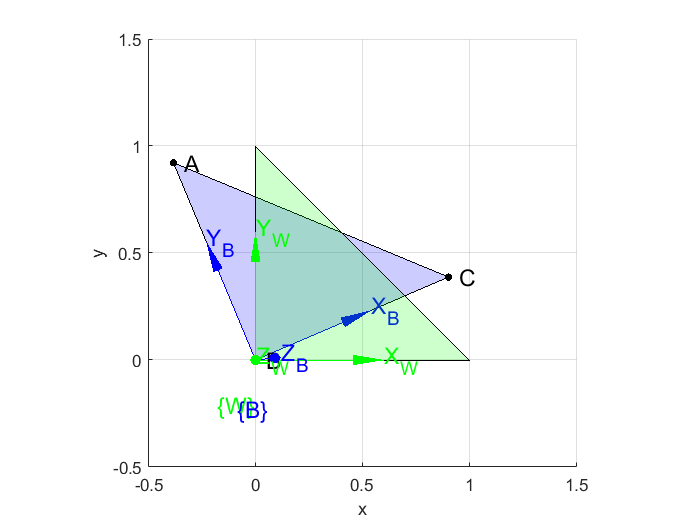

trplot(eye(4), 'frame','W','length',0.6,'text_opts', {'FontSize', 14},'arrow','color', 'g','thick',1)
trplot(B, 'frame','B','length',0.6,'text_opts', {'FontSize', 14},'arrow','color', 'b','thick',1)

## Unitary vectors from P_B

 AB=(FK_A(1:3,1)-FK_A(1:3,2))/norm(FK_A(1:3,1)-FK_A(1:3,2)); % Vector pointing A 
 norm(AB)

ans = 1

 CB=(FK_A(1:3,3)-FK_A(1:3,2))/norm(FK_A(1:3,2)-FK_A(1:3,3)); % Vector pointing C
 norm(CB)

ans = 1

## Frame description extracted fron the triangles 

Orientation vector: Approach: â --> Z; See page 40 of the Peter Corke book: Robotics, Vision and Control 

 Z_B=cross(CB, AB)/norm(cross(CB, AB))% Perpendicular to BA & CB equivalent to â; Z point up

Z_B =     0.1977
    0.0198
    0.9801


 O_B_A =oa2r(AB, Z_B); % AB is the orientation vector (y axis ô) and Z_B is tha aproach axis (z axis â). The result ^n is in x axis
     

Displaying the {nB} coincident with {B}

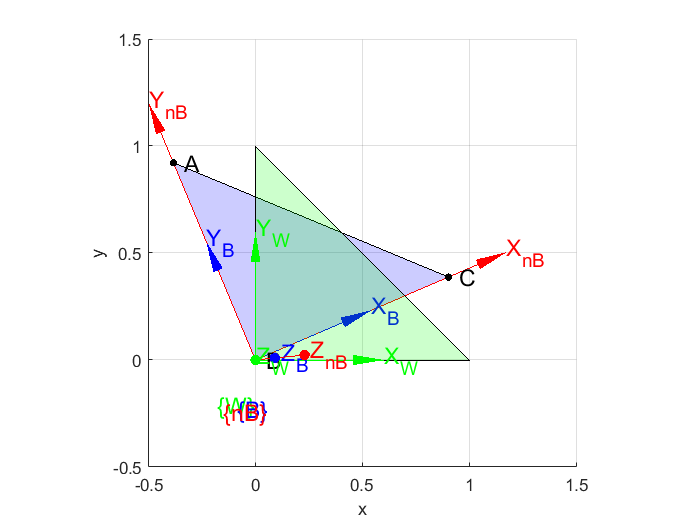

 trplot(O_B_A, 'frame','nB','length',1.3,'text_opts', {'FontSize', 14},'arrow','color', 'r','thick',1)

## Testing

FK_An=r2t(O_B_A)*P_B

FK_An =    -0.3836         0    0.9021
    0.9216         0    0.3875
    0.0587         0   -0.1898
    1.0000    1.0000    1.0000


FK_A

FK_A =    -0.3836         0    0.9021
    0.9216         0    0.3875
    0.0587         0   -0.1898
    1.0000    1.0000    1.0000
